# Getting Model Output 

## Load in track matfiles and create structs

colHeadings = {'Years' 'Data'};
DataPath = '/mnt/storage6/clark/ANHA4/ANHA4-ECP017-LAB60/';
DataPath2 = '/mnt/storage6/clark/ANHA4/ANHA4-ECP017-SPG12/';

% Comment the ones that aren't necessary

load ERA5Labwinters.mat
ERA5LabW = cell2struct(ERA5Labwinters,colHeadings,2);
for ii = 1:18   % Masking longitude values into -180 to 180
    [rows, cols] = size(ERA5LabW(ii).Data);
    ERA5LabWA = table2array(ERA5LabW(ii).Data);
    for k = 1:rows
        if ERA5LabWA(k,8) > 180
            ERA5LabWA(k,8) = (ERA5LabWA(k,8)-360);
            ERA5LabW(ii).Data = array2table(ERA5LabWA);
            ERA5LabW(ii).Data = renamevars(ERA5LabW(ii).Data,["ERA5LabWA1","ERA5LabWA2","ERA5LabWA3","ERA5LabWA4","ERA5LabWA5","ERA5LabWA6","ERA5LabWA7","ERA5LabWA8","ERA5LabWA9","ERA5LabWA10"],["track_id","year","month","day","hour","i","j","lon","lat","msl"]);
        end
    end
end

% load ERA5Nordicwinters.mat
% ERA5NordicW = cell2struct(ERA5Nordicwinters,colHeadings,2);
% for ii = 1:18   % Masking longitude values into -180 to 180
%     [rows, cols] = size(ERA5NordicW(ii).Data);
%     ERA5NordicWA = table2array(ERA5NordicW(ii).Data);
%     for k = 1:rows
%         if ERA5NordicWA(k,8) > 180
%             ERA5NordicWA(k,8) = (ERA5NordicWA(k,8)-360);
%             ERA5NordicW(ii).Data = array2table(ERA5NordicWA);
%             ERA5NordicW(ii).Data = renamevars(ERA5NordicW(ii).Data,["ERA5NordicWA1","ERA5NordicWA2","ERA5NordicWA3","ERA5NordicWA4","ERA5NordicWA5","ERA5NordicWA6","ERA5NordicWA7","ERA5NordicWA8","ERA5NordicWA9","ERA5NordicWA10"],["track_id","year","month","day","hour","i","j","lon","lat","msl"]);
%         end
%     end
% end

% load CGRFLabwinters.mat
% CGRFLabW = cell2struct(CGRFLabwinters,colHeadings,2);
% for ii = 1:18   % Masking longitude values into -180 to 180
%     [rows, cols] = size(CGRFLabW(ii).Data);
%     CGRFLabWA = table2array(CGRFLabW(ii).Data);
%     for k = 1:rows
%         if CGRFLabWA(k,8) > 180
%             CGRFLabWA(k,8) = (CGRFLabWA(k,8)-360);
%             CGRFLabW(ii).Data = array2table(CGRFLabWA);
%             CGRFLabW(ii).Data = renamevars(CGRFLabW(ii).Data,["CGRFLabWA1","CGRFLabWA2","CGRFLabWA3","CGRFLabWA4","CGRFLabWA5","CGRFLabWA6","CGRFLabWA7","CGRFLabWA8","CGRFLabWA9","CGRFLabWA10"],["track_id","year","month","day","hour","i","j","lon","lat","msl"]);
%         end
%     end
% end

% load CGRFNordicwinters.mat
% CGRFNordicW = cell2struct(CGRFNordicwinters,colHeadings,2);
% for ii = 1:18   % Masking longitude values into -180 to 180
%     [rows, cols] = size(CGRFNordicW(ii).Data);
%     CGRFNordicWA = table2array(CGRFNordicW(ii).Data);
%     for k = 1:rows
%         if CGRFNordicWA(k,8) > 180
%             CGRFNordicWA(k,8) = (CGRFNordicWA(k,8)-360);
%             CGRFNordicW(ii).Data = array2table(CGRFNordicWA);
%             CGRFNordicW(ii).Data = renamevars(CGRFNordicW(ii).Data,["CGRFNordicWA1","CGRFNordicWA2","CGRFNordicWA3","CGRFNordicWA4","CGRFNordicWA5","CGRFNordicWA6","CGRFNordicWA7","CGRFNordicWA8","CGRFNordicWA9","CGRFNordicWA10"],["track_id","year","month","day","hour","i","j","lon","lat","msl"]);
%         end
%     end
% end

## Extracting temperature and salinity profiles for each point along storm track

## Setting up for extracting profile data

% Define the following:
ix = 2010  % year of interest

ix = 2010

d = 1       % track ID of interest

d = 1

% Note: at the bottom, manually change the year in matdir so that it saves
% in the right folder

yy = ix - 2001

yy = 9

track = ERA5LabW(yy).Data(ERA5LabW(yy).Data.track_id == d, :);
track = track(1:8:end, :);
c = height(track)

c = 3

CaseConf = '2_ANHA4-ECP017';
CaseConf2 = '1_ANHA4-ECP017';
Mesh_hgr='/mnt/storage6/clark/NEMO_meshes/AGRIF/LAB60/LabSea-domain/2_LAB60_mesh_hgr.nc';
Mesh_hgr2='/mnt/storage6/clark/NEMO_meshes/AGRIF/LAB60/SPG-domain/1_SPG12_meshmask.nc';
Ystart = 0; Xstart = 0;
Ycount =  2659 %max(track.lat)-min(track.lat)+1;

Ycount = 2659

Xcount =  1179 %max(track.lon)-min(track.lon)+1;

Xcount = 1179

colHeadings2 = ["Point" "Date" "Lat" "Lon" "Data"];  % Create a table to save the TS data into 
TSprofiles = cell(c,5);
% Profiles = cell(7,3);
varnamesp = {'Time' 'T' 'S'}; % Time = days from the date where cyclone center passes over the point
% points = cat(1,varnamesp,points);

## Extracting profiles of track points (-3 days to +3 days)

monlen = [31;28;31;30;31;30;31;31;30;31;30;31];

% For each point/timestep along the track
for a = 1:c     % where c is the final timestep in the track
    Profiles = cell(7,3);
    year = ix;
    month = track.month(a);
    day = track.day(a); 
    if year == 2016||2012||2008||2004   % Taking into account leap days
        monlen(2,1) = 29;
    else
        monlen(2,1) = 28;
    end
    
    Lat = track.lat(a); Lon = track.lon(a);
    TSprofiles{a,1} = a; TSprofiles{a,3} = Lat; TSprofiles{a,4} = Lon; % Write into the cell that will become part of the struct
    
    for b = -3:3     % For each day surrounding each point of the track
        % Defining past and future dates for each point along track for the time evolution
        Profiles{b+4,1} = b;
        % Adjusting date near month boundaries
        if day+b <= 0     % start of the month, step is in the past
            month = month-1;
            day = monlen(month-1,1)+(day+b);
        elseif day+b > monlen(month,1)    % end of the month, step is in the future
            month = month+1;
            day = day+b-monlen(month,1);
        else
            month = track.month(a);
            day = day+b;       
        end
        % Specifying file for current timestep
        TimeTag = ['y',num2str(year),'m',num2str(month,'%02d'),'d',num2str(day,'%02d')];
        File = [DataPath,CaseConf,'_',TimeTag,'_gridT.nc'];
        xx = GetNcVar(Mesh_hgr,'nav_lon',[Xstart Ystart],[Xcount Ycount]);
        yy = GetNcVar(Mesh_hgr,'nav_lat',[Xstart Ystart],[Xcount Ycount]); 
        [indY, indX] = GetXYfromLatLon(Lat,Lon,yy,xx); % Specifying the lat and lon for which to open the file
        if any(Lat<min(yy) | Lat>max(yy) | Lon<min(xx) | Lon>max(xx))     % If point is outside the bounds of LAB60
            Xcount = 724; Ycount = 694; 
            File = [DataPath2,CaseConf2,'_',TimeTag,'_gridT.nc'];
            XX = GetNcVar(Mesh_hgr2,'nav_lon',[Xstart Ystart],[Xcount Ycount]); % Use SPG12 mask
            YY = GetNcVar(Mesh_hgr2,'nav_lat',[Xstart Ystart],[Xcount Ycount]);
            [indY, indX] = GetXYfromLatLon(Lat,Lon,YY,XX);  
        end      
     
        % Getting variables and writing T/S tables into cell
        Zcount = 75;        % Full depth (75 levels in NEMO)
        Depth = GetNcVar(File,'deptht'); 
        Depth = Depth.';    % Set depth to the same orientation as the other variables
        Temperature = GetNcVar(File,'votemper',[indX indY 0 0],[1 1 Zcount 1]);
        Salinity = GetNcVar(File,'vosaline',[indX indY 0 0],[1 1 Zcount 1]);
        T = table(Depth,Temperature);
        S = table(Depth,Salinity);
        Profiles{b+4,2} = T; % Write variables into the table
        Profiles{b+4,3} = S;
        TSprofiles{a,2} = TimeTag;
    end
    Profiles = cell2table(Profiles,"VariableNames",varnamesp);
    TSprofiles{a,5} = Profiles;
end

Search radius exceeded 1 degree before finding a solution, this might be a problem!


% Combine the matfiles for all the timesteps into one struct for the track
TSprofiles = cell2struct(TSprofiles,colHeadings2,2);
matdir = './TSprofiles/ERA5/2010';      % change dataset and year manually so it saves to the right folder
matname = fullfile(matdir, ['Track',num2str(d),'TSprofiles.mat']);
save(matname,"TSprofiles",'-mat'); 
clear Temperature Depth Salinity % struct saved as matfile, can load up the matfile to plot the T/S with depth below each point


% If loading in multiple track structs, manually rename them with corresponding track numbers 
% before loading in the next since they all load in as 'TSprofile'

% When analyzing, remember the central pressure of the cyclone at each point is
% recorded in the 'track' table

## Contour plots of TEMPERATURE with depth (interpolated, actual T)

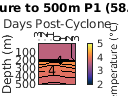

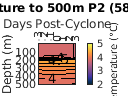

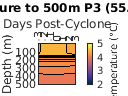

% Things that need to be adjusted for each cyclone: ctrl+f for 'here'

% Load in the appropriate track's TS file from the right subdirectory
load ./TSprofiles/ERA5/2010/Track1TSprofiles.mat;   % here
matdir2 = './Figures/ERA5plots/TSprofiles/2010';       % here
% w = width(TSprofiles(1).Data)   % Setting up matrices for contour plots (useful when T/S has a varying number of columns, eg. for different track lengths)

for i1 = 1:c    % Looping over all points along the track
    Lat = TSprofiles(i1).Lat;
    Lon = TSprofiles(i1).Lon;
    for i2 = 1:7    % Looping over each timestep for each point along the track (-3:+3)
        T = table2array(TSprofiles(i1).Data.T{i2});    % creating matrix of variables for contour()
        Depth = T(:,1);
        if i2 == 1
            Temperature = T(:,2);
        else
            TT = T(:,2);
            Temperature = cat(2,Temperature,TT);
        end 
        Time = TSprofiles(i1).Data.Time;
        Time = Time.';
        Time2 = 1:1:7;
        xnames = Time; 
    end

    % Setting up for automated interval assignment 
    minT = floor(min(Temperature(Temperature>0))); minT = min(minT);    % Temp>0 bc there are a bunch of zero values bringing down the colourbar
    maxT = ceil(max(Temperature)); maxT = max(maxT);
    % Assigning intervals for the contours
    a = minT:0.1:maxT; %aa = 2:1:9;  
    %a = cat(2,aa,a);    
%     labelsT = a(1,1:2:end);     % Which contours should be labelled in the contour plot
   
    % Figures
    figure                    % Plotting top 500m
    [C,h] = contourf(Time2,Depth(1:40),Temperature(1:40,:),a,"ShowText","on"); 
    set(gca,'YDir','reverse','XAxisLocation','top','XTick',1:1:7)
    xlabel('Days Post-Cyclone')
    xticklabels(xnames(1:7))
    ylabel('Depth (m)')
    cc = colorbar;
    cc.Label.String = 'Temperature (°C)';
    caxis([minT,maxT]);  
    cmocean('thermal');
%     clabel(C,h,labelsT);
    title(['Temperature to 500m P', num2str(i1),' (',num2str(Lat),',',num2str(Lon),')'])
    exportgraphics(gca,['2010_Track1_',num2str(i1),'_T_500m.png'],"Resolution",300) % here
    
%     figure                    % Plotting top 1000m
%     contourf(Time2,Depth(1:47),Temperature(1:47,:),a); %,"LineStyle","none"
%     set(gca,'YDir','reverse','XAxisLocation','top','XTick',1:1:7)
%     xlabel('Days Post-Cyclone')
%     xticklabels(xnames(1:7))
%     ylabel('Depth (m)')
%     cc = colorbar;
%     cc.Label.String = 'Temperature (°C)';
%     caxis([2,5]);   % here
%     title(['Temperature to 1000m P', num2str(i1),' (',num2str(Lat),',',num2str(Lon),')'])
%     exportgraphics(gca,['2010_Track1_',num2str(i1),'_T_1000m.png'],"Resolution",300)    % here
end


% Note: contour() wants to take a matrix (ARRAY, not cell) as the third parameter, Z


## Contour plots of SALINITY with depth (interpolated, actual S)

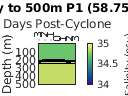

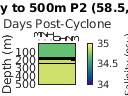

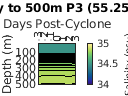

% Things that need to be adjusted for each cyclone: ctrl+f for 'here'

% Load in the appropriate track's TS file from the right subdirectory
load ./TSprofiles/ERA5/2010/Track1TSprofiles.mat;   % here
% matdir2 = './Figures/ERA5plots/TSprofiles/2010';       % here
% w = width(TSprofiles(1).Data)   % Setting up matrices for contour plots (useful when T/S has a varying number of columns, eg. for different track lengths)

for i1 = 1:c    % Looping over all points along the track
    Lat = TSprofiles(i1).Lat;
    Lon = TSprofiles(i1).Lon;
    for i2 = 1:7    % Looping over each timestep for each point along the track (-3:+3)
        S = table2array(TSprofiles(i1).Data.S{i2});    % creating matrix of variables for contour()
        Depth = S(:,1);
        if i2 == 1
            Salinity = S(:,2);
        else
            SS = S(:,2);
            Salinity = cat(2,Salinity,SS);
        end 
        Time = TSprofiles(i1).Data.Time;
        Time = Time.';
        Time2 = 1:1:7;
        xnames = Time; 
    end
    minS = floor(min(Salinity(Salinity>0))); minS = min(minS);
    maxS = ceil(max(Salinity)); maxS = max(maxS); 
    b = minS:0.02:maxS;  % Assigning intervals for the contours (adjust interval if there are too many or too few contours)
    labelsS = b(1,1:2:end);

    % Figures
    figure                    % Plotting top 500m
    [C,h] = contourf(Time2,Depth(1:40),Salinity(1:40,:),b,"ShowText","on"); 
    set(gca,'YDir','reverse','XAxisLocation','top','XTick',1:1:7)
    xlabel('Days Post-Cyclone')
    xticklabels(xnames(1:7))
    ylabel('Depth (m)')
    cc = colorbar;
    cc.Label.String = 'Salinity (psu)';
    caxis([minS,maxS]);  % here   % NOTE: just looked and manually picked min/max for the colourbar based on values in TSprofiles
    clabel(C,h,labelsS);
    cmocean('haline');
    title(['Salinity to 500m P', num2str(i1),' (',num2str(Lat),',',num2str(Lon),')'])
    exportgraphics(gca,['2010_Track1_',num2str(i1),'_S_500m.png'],"Resolution",300) % here
end

    
%     figure                    % Plotting top 1000m
%     contourf(Time2,Depth(1:47),Salinity(1:47,:),b); %,"LineStyle","none"
%     set(gca,'YDir','reverse','XAxisLocation','top','XTick',1:1:7)
%     xlabel('Days Post-Cyclone')
%     xticklabels(xnames(1:7))
%     ylabel('Depth (m)')
%     cc = colorbar;
%     cc.Label.String = 'Salinity (psu)';
%     caxis([minS,maxS]);  
%     title(['Salinity to 1000m P', num2str(i1),' (',num2str(Lat),',',num2str(Lon),')'])
%     exportgraphics(gca,['2010_Track1_',num2str(i1),'_S_1000m.png'],"Resolution",300)    % here
% end

% Note: contour() wants to take a matrix (ARRAY, not cell) as the third parameter, Z


## Contour plots of T & S with depth (ANOMALY from +0 days)

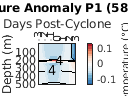

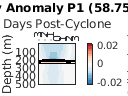

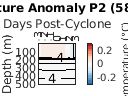

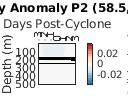

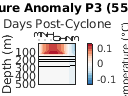

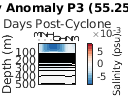

% Run the first two sections first!
% Things that need to be adjusted for each cyclone: ctrl+f for 'here'

% Load in the appropriate track's TS file from the right subdirectory
load ./TSprofiles/ERA5/2010/Track1TSprofiles.mat;   % here

for i1 = 1:c    % Looping over all points along the track
    Lat = TSprofiles(i1).Lat;
    Lon = TSprofiles(i1).Lon;
    for i2 = 1:7    % Looping over each timestep for each point along the track (-3:+3)
        T = table2array(TSprofiles(i1).Data.T{i2});
        S = table2array(TSprofiles(i1).Data.S{i2});    % creating matrix of variables for contour()
        Depth = T(:,1);
        if i2 == 1
            Temperature = T(:,2);
            Salinity = S(:,2);
        else
            TT = T(:,2);
            Temperature = cat(2,Temperature,TT);
            SS = S(:,2);
            Salinity = cat(2,Salinity,SS);
        end 
        Time = TSprofiles(i1).Data.Time;
        Time = Time.';
        Time2 = 1:1:7;
        xnames = Time;  
    end

    % Calculating anomalies in T/S from day 0
%     h = height(Temperature);
%     w = width(Temperature);
%     TemperatureAnom = cell(h,w);
%     SalinityAnom = cell(h,w);
%     day0T = Temperature(:,4);
%     day0S = Salinity(:,4);
%     for i3 = 1:h
%         for i4 = 1:w
%             TemperatureAnom{i3,i4} = Temperature(i3,i4) - day0T(i3);
%             SalinityAnom{i3,i4} = Salinity(i3,i4) - day0S(i3);
%         end
%     end
%     TemperatureAnom = cell2mat(TemperatureAnom);
%     SalinityAnom = cell2mat(SalinityAnom);
%     newTAnom = TemperatureAnom;
%     newSAnom = SalinityAnom;
     
    % Calculating anomalies in T/S from day -3
    h = height(Temperature);
    w = width(Temperature);
    TemperatureAnom = cell(h,w);
    SalinityAnom = cell(h,w);
    neg3T = Temperature(:,1);
    neg3S = Salinity(:,1);
    for i3 = 1:h
        for i4 = 1:w
            TemperatureAnom{i3,i4} = Temperature(i3,i4) - neg3T(i3);
            SalinityAnom{i3,i4} = Salinity(i3,i4) - neg3S(i3);
        end
    end
    TemperatureAnom = cell2mat(TemperatureAnom);
    SalinityAnom = cell2mat(SalinityAnom);
    newTAnom = TemperatureAnom;
    newSAnom = SalinityAnom;




    % min and max of the ACTUAL T/S values
    minT = round(min(Temperature)); minT = min(minT);     % Isolating the single lowest and highest values of T/S 
    maxT = round(max(Temperature)); maxT = max(maxT);     % to set the contour intervals
    minS = round(min(Salinity),1); minS = min(minS);
    maxS = round(max(Salinity),1); maxS = max(maxS);      % (rounding to integers for T, 1 decimal for S)

    % min and max of ANOMALY T/S values
    minmaxT = max(round(abs(TemperatureAnom),2)); minmaxT = max(minmaxT);
    minmaxS = max(round(abs(SalinityAnom),3)); minmaxS = max(minmaxS);
   
    % Assigning intervals for the contours
    a = minT:0.2:maxT;               % actual T/S
    b = minS:0.02:maxS; 
    aa = -minmaxT:0.01:minmaxT;      % anomaly T/S
    bb = -minmaxS:0.001:minmaxS;
    
    labelsS = b(1,1:2:end);     % Which contours should be labelled in the contour plot
    ticksT = aa(1,1:2:end);     % Setup for discretizing colourbar
    ticklabelsT = num2str(ticksT);
    ticklabelsS = num2str(bb);
    
    % Rescaling data to discretize colourbar
    for i = 2:length(ticksT)    % Temperature 
        ind = TemperatureAnom>ticksT(i-1) & TemperatureAnom<=ticksT(i);
        newTAnom(ind) = rescale(TemperatureAnom(ind),ticksT(i-1),ticksT(i));
    end
    for i = 2:length(bb)        % Salinity
        ind = SalinityAnom>bb(i-1) & SalinityAnom<=bb(i);
        newSAnom(ind) = rescale(SalinityAnom(ind),bb(i-1),bb(i));
    end

    figure      % Plotting top 500m TEMPERATURE
    contourf(Time2,Depth(1:40),TemperatureAnom(1:40,:),aa,"LineStyle","none"); 
    hold on
    [Cc,Hh] = contour(Time2,Depth(1:40),Temperature(1:40,:),a,'k',"ShowText","on");
    set(gca,'YDir','reverse','XAxisLocation','top','XTick',1:1:7)
    xlabel('Days Post-Cyclone')
    xticklabels(xnames(1:7))
    ylabel('Depth (m)')
    cc = colorbar();
%     set(cc,'Ticks',ticksT,'TickLabels',ticklabelsT);
    colormap(redblueTecplot(17));   % however many colours/shades you want the colourmap to use (check aa)
    cc.Label.String = 'Temperature (°C)';
    caxis([-minmaxT,minmaxT]); 
    title(['Temperature Anomaly P', num2str(i1),' (',num2str(Lat),',',num2str(Lon),')'])
    exportgraphics(gca,['2010_Track1_',num2str(i1),'_T_anom.png'],"Resolution",300) % here

    figure      % Plotting top 500m SALINITY             
    contourf(Time2,Depth(1:40),SalinityAnom(1:40,:),bb,"LineStyle","none");
    hold on
    [C,hh] = contour(Time2,Depth(1:40),Salinity(1:40,:),b,'k',"ShowText","on");
    set(gca,'YDir','reverse','XAxisLocation','top','XTick',1:1:7)
    xlabel('Days Post-Cyclone')
    xticklabels(xnames(1:7))
    ylabel('Depth (m)')
    cc = colorbar();
%     set(cc,'Ticks',bb,'TickLabels',ticklabelsS);
    colormap(redblueTecplot(17));    % however many colours/shades you want the colourmap to use (check bb)
    cc.Label.String = 'Salinity (psu)';
    clabel(C,hh,labelsS);
    caxis([-minmaxS,minmaxS]);  % here   % NOTE: just looked and manually picked min/max for the colourbar based on values in TSprofiles
    title(['Salinity Anomaly P', num2str(i1),' (',num2str(Lat),',',num2str(Lon),')'])
    exportgraphics(gca,['2010_Track1_',num2str(i1),'_S_anom.png'],"Resolution",300) % here
end

## Plotting atmospheric data timeseries

## Outdated: Contour plots for -3days

% -3 DAYS
w = width(TSprofiles(4).Data) 
T = table2array(TSprofiles(4).Data);    % creating matrix of variables for contour()
TSprofiles = (TSprofiles(6).Data.Point);
Depth = T(:,1);
Temperature = T(:,2:w);

for b = 1:c                   % for defining the x-axis labels when plotting multiple points along the track at the sane tune
    xb = TSprofiles(i1).Lat;
    xc = TSprofiles(i1).Lon;
    xnames{1,b} = ([num2str(b),' (',num2str(xb),',',num2str(xc),')']);
end

figure                    % Plotting down to 3500m
contourf(TSprofiles,Depth(1:63),Temperature(1:63,:),20); 
set(gca,'YDir','reverse','XAxisLocation','top','XTick',1:1:c)
xlabel('Position Along Track')
xticklabels(xnames(1:c))
ylabel('Depth')
colorbar
caxis([2,17]);
title('Temperature to 3500m -3 days')
exportgraphics(gca,"2010_Track1_T_-3d_3500m.png","Resolution",300)
% Note: contour() wants to take a matrix (ARRAY, not cell) as the third parameter, Z

figure                    % Plotting top 850m
contourf(TSprofiles,Depth(1:45),Temperature(1:45,:),a); 
set(gca,'YDir','reverse','XAxisLocation','top','XTick',1:1:c)
xlabel('Position Along Track')
xticklabels(xnames(1:c))
ylabel('Depth')
colorbar
caxis([2,17]);
title('Temperature to 850m -3 days')
exportgraphics(gca,"2010_Track1_T_-3d_850m.png","Resolution",300)

## Outdated: Contour plots for +3days

% +3 DAYS
w = width(TSprofiles(7).Data) 
T = table2array(TSprofiles(7).Data);    % creating matrix of variables for contour()
TSprofiles = (TSprofiles(9).Data.Point);
Depth = T(:,1);
Temperature = T(:,2:w); 

figure                    % Plotting down to 3500m
contourf(TSprofiles,Depth(1:63),Temperature(1:63,:),20); 
set(gca,'YDir','reverse','XAxisLocation','top','XTick',1:1:c)
xlabel('Position Along Track')
xticklabels(xnames(1:c))
ylabel('Depth')
colorbar
caxis([2,17]);
title('Temperature to 3500m +3 days')
exportgraphics(gca,"2010_Track1_T_+3d_3500m.png","Resolution",300)
% Note: contour() wants to take a matrix (ARRAY, not cell) as the third parameter, Z

figure                    % Plotting top 850m
contourf(TSprofiles,Depth(1:45),Temperature(1:45,:),a); 
set(gca,'YDir','reverse','XAxisLocation','top','XTick',1:1:c)
xlabel('Position Along Track')
xticklabels(xnames(1:c))
ylabel('Depth')
colorbar
caxis([2,17]);
title('Temperature to 850m +3 days')
exportgraphics(gca,"2010_Track1_T_+3d_850m.png","Resolution",300)


## Outdated: Adding track-3days and track+3days into TSprofiles struct

% -p = date in the past, -f = date in the future
monlen = [31;28;31;30;31;30;31;31;30;31;30;31];

% Load in the appropriate track's TS file from the right subdirectory
load ./TSprofiles/ERA5/2010/Track1TSprofiles.mat;

% loop through timesteps of track and for each one, define a date 3 days in the past and one 3 days in the future
% -3 DAYS
for a = 1:c    
    year = ix;
    month = track.month(a);
    day = track.day(a);
    if year == 2016||2012||2008||2004   % Taking into account leap days
        monlen(2,1) = 29;
    else
        monlen(2,1) = 28;
    end
    if day <= 3     % if day is within the first 3 days of the month
        monthp = month-1;
        dayp = monlen(month-1,1)-(3-day);
    else
        monthp = month;
        dayp = day-3;
    end
    TimeTagP = ['y',num2str(year),'m',num2str(monthp,'%02d'),'d',num2str(dayp,'%02d')];
    File = [DataPath,CaseConf,'_',TimeTagP,'_gridT.nc'];  % Specified file for current timestep
    xx = GetNcVar(Mesh_hgr,'nav_lon',[Xstart Ystart],[Xcount Ycount]);
    yy = GetNcVar(Mesh_hgr,'nav_lat',[Xstart Ystart],[Xcount Ycount]);
    Lat = track.lat(a); Lon = track.lon(a);
    [indY, indX] = GetXYfromLatLon(Lat,Lon,yy,xx);  % Specifying the lat and lon for which to open the file
    if any(Lat<min(yy) | Lat>max(yy) | Lon<min(xx) | Lon>max(xx))     % If point is outside the bounds of LAB60
        Xcount = 724; Ycount = 694;
        XX = GetNcVar(Mesh_hgr2,'nav_lon',[Xstart Ystart],[Xcount Ycount]); % Use SPG12 mask
        YY = GetNcVar(Mesh_hgr2,'nav_lat',[Xstart Ystart],[Xcount Ycount]);
        [indY, indX] = GetXYfromLatLon(Lat,Lon,YY,XX);
        File = [DataPath2,CaseConf2,'_',TimeTag,'_gridT.nc'];
    end
    Zcount = 75;        % Full depth (75 levels in NEMO)
    Depth = GetNcVar(File,'deptht'); 
    Depth = Depth.';    % Set depth to the same orientation as the other variables
    Temperature = GetNcVar(File,'votemper',[indX indY 0 0],[1 1 Zcount 1]);
    Salinity = GetNcVar(File,'vosaline',[indX indY 0 0],[1 1 Zcount 1]);
    PointNumber = a;
%     TSprofiles{a,1} = PointNumber; TSprofiles{a,2} = Lat; TSprofiles{a,3} = Lon;  % Create cell to put points and corresponding location
     if a == 1
        T = table(Depth,Temperature);
        T = renamevars(T,"Temperature","Temperature1");
    else
        T2 = table(Temperature);
        T2 = renamevars(T2,"Temperature",['Temperature',num2str(a)]);
        T = cat(2,T,T2);
    end 
    if a == 1
        S = table(Depth,Salinity);
        S = renamevars(S,"Salinity","Salinity1");
    else
        S2 = table(Salinity);
        S2 = renamevars(S2,"Salinity",['Salinity',num2str(a)]);
        S = cat(2,S,S2);
    end  
end
Points = cell2table(TSprofiles,"VariableNames",varnamesp);
TSprofiles(4).Variable = "-3 Temperature"; TSprofiles(4).Data = T; % Write variables into the struct
TSprofiles(5).Variable = "-3 Salinity"; TSprofiles(5).Data = S;
TSprofiles(6).Variable = "-3 Points"; TSprofiles(6).Data = Points;
clear Temperature Depth Salinity

% +3 DAYS
for a = 1:c    
    year = ix;
    if year == 2016||2012||2008||2004   % Taking into account leap days
        monlen(2,1) = 29;
    else
        monlen(2,1) = 28;
    end
    if day >= monlen(month,1)-2     % if day is within 3 days of the end of the month
        monthf = month+1;
        dayf = 3-(monlen(month,1)-day);
    else
        monthf = month;
        dayf = day+3;
    end
    TimeTagF = ['y',num2str(year),'m',num2str(monthf,'%02d'),'d',num2str(dayf,'%02d')];
    File = [DataPath,CaseConf,'_',TimeTagF,'_gridT.nc'];  % Specified file for current timestep
    xx = GetNcVar(Mesh_hgr,'nav_lon',[Xstart Ystart],[Xcount Ycount]);
    yy = GetNcVar(Mesh_hgr,'nav_lat',[Xstart Ystart],[Xcount Ycount]);
    Lat = track.lat(a); Lon = track.lon(a);
    [indY, indX] = GetXYfromLatLon(Lat,Lon,yy,xx);  % Specifying the lat and lon for which to open the file
    Zcount = 75;        % Full depth (75 levels in NEMO)
    Depth = GetNcVar(File,'deptht'); 
    Depth = Depth.';    % Set depth to the same orientation as the other variables
    Temperature = GetNcVar(File,'votemper',[indX indY 0 0],[1 1 Zcount 1]);
    Salinity = GetNcVar(File,'vosaline',[indX indY 0 0],[1 1 Zcount 1]);
    PointNumber = a;
    TSprofiles{a,1} = PointNumber; TSprofiles{a,2} = Lat; TSprofiles{a,3} = Lon;  % Create cell to put points and corresponding location
    if a == 1
        T = table(Depth,Temperature);
        T = renamevars(T,"Temperature","Temperature1");
    else
        T2 = table(Temperature);
        T2 = renamevars(T2,"Temperature",['Temperature',num2str(a)]);
        T = cat(2,T,T2);
    end 
    if a == 1
        S = table(Depth,Salinity);
        S = renamevars(S,"Salinity","Salinity1");
    else
        S2 = table(Salinity);
        S2 = renamevars(S2,"Salinity",['Salinity',num2str(a)]);
        S = cat(2,S,S2);
    end  
end
Points = cell2table(TSprofiles,"VariableNames",varnamesp);
TSprofiles(7).Variable = "+3 Temperature"; TSprofiles(7).Data = T; % Write variables into the struct
TSprofiles(8).Variable = "+3 Salinity"; TSprofiles(8).Data = S;
TSprofiles(9).Variable = "+3 Points"; TSprofiles(9).Data = Points;
matdir = './TSprofiles/ERA5/2010';      % change dataset and year manually so it saves to the right folder
matname = fullfile(matdir, ['Track',num2str(b),'TSprofiles.mat']);
save(matname,"TSprofiles",'-mat'); 
clear Temperature Depth Salinity


## Retrieving data from existing timeseries of HC, FWT, ConvR

% Define a TimeTag for easily referring to the names of matfiles
% Write loops asking matlab to retrieve ONLY the data from the matfiles
% that I've specified with the TimeTag, then can do the same by specifying
% which XYZ to take
% Note: mnt/storage3/pouneh/movies/ECP017/HC_R_LAB60/matfile/ has 2010-2013

% for year = YearStart:YearEndset 
%     for month = m%:mm  % set m = month of interest; mm if a cyclone exists over a change in month
%         for daystart:dayend
%             TimeTag=['y',num2str(year),'m',num2str(mon,'%02d'),'d',num2str(day,'%02d')];
%             matdirHC=['mnt/storage3/pouneh/movies/ECP017/HC_R_LAB60/matfile/','HeatCont_',num2str(TimeTag),'.mat'];
%             matdirFW=['mnt/storage3/pouneh/movies/ECP017/FWT_R/matfile/','FW_',num2str(TimeTag),'.mat'];            % changed these paths, were all ./ECP027 before
%             matdirConvR=['mnt/storage3/pouneh/movies/ECP017/ConvE_R/matfile/','ConvE_R_threeDepth_',num2str(TimeTag),'.mat'];
%             if exist(matdirHC,'file')
%                 eval(['load ',matdirHC,' HC HC1 HC2 Zcount Zcount1 Zcount2 nav_lat nav_lon Thickness Cp DensRef '])
%                 eval(['load ',matdirFW,' FWC FWC1 FWC2 Sref '])
%                 eval(['load ',matdirConvR,' Conv Conv1 Conv2 '])
%                 figure 
%                 hold on
%                 plot(date,Conv)
%         end
%     end
    